# **Cinemática Inversa Manipulador 4R**

# **Felipe Forero - Iván Hernández - Juan Ramirez - Felipe Zuleta**

Para el desarrollo del modelo cinemático inverso del manipulador, se utiliza un acercamiento geométrico del mismo.

Para encontrar las variables articulares del manipulador, se debe partir de la ubicación del TCP de la herramienta, para el desarrollo de este análisis comenzaremos observando el manipulador desde una vista superior, en donde las coordenadas x e y de la herramienta saltan a la vista, veáse la siguiente figura.

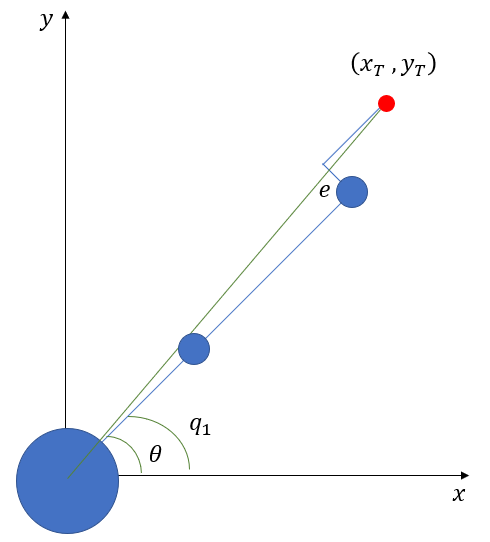

Este sería un caso general de la ubicación de la herramienta, para facilitar el proceso y pensando que la herramienta utilizada será un marcador, que en primera instancia dibujará en el plano XY, se definirá el ángulo $q_4$ como - 90° para que el TCP del marcador apunte en la dirección del suelo, de esta manera, el diagrama se simplifica de la siguiente forma.

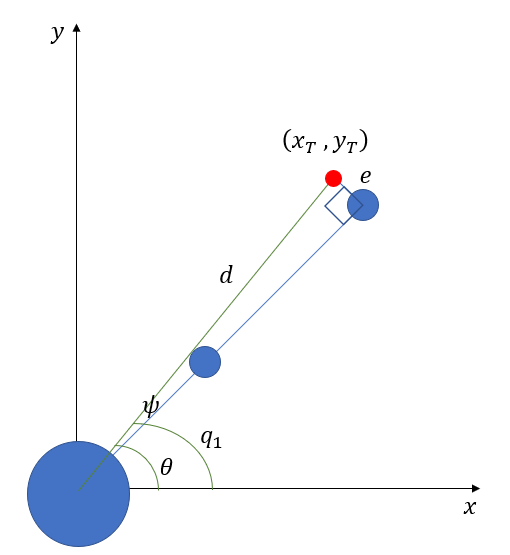

De la figura, se observa como los ángulos $\theta$, $q_1$ y $\psi$; así como la distancia $d$ pueden determinarse fácilmente.


$$d=\sqrt{x_T^2 +y_T^2 }$$



$$\psi =\mathrm{atan2}\;\left(e\;,d\right)$$



$$\theta \;=\mathrm{atan2}\;\left(y_T \;,x_T \right)$$



$$q_1 =\theta -\psi$$


syms xT yT zT
e = 5;
l2 = 10;
l3 = 8;
l4 = 5;
q4 = -90;
z0 = 10;
theta = atan2(yT,xT)

$$theta = \text{atan2}\left(\mathrm{yT},\mathrm{xT}\right)$$

d = sqrt(xT^2 + yT^2)

$$d = \sqrt{{\mathrm{xT}}^{2}+{\mathrm{yT}}^{2}}$$

psi = atan2(e,d)

$$psi = \text{atan2}\left(5,\sqrt{{\mathrm{xT}}^{2}+{\mathrm{yT}}^{2}}\right)$$

q1 = theta-psi

$$q1 = \text{atan2}\left(\mathrm{yT},\mathrm{xT}\right)-\text{atan2}\left(5,\sqrt{{\mathrm{xT}}^{2}+{\mathrm{yT}}^{2}}\right)$$

Para continuar con el modelo cinemático inverso, se debe conocer la orientación deseada de la herramienta respecto al plano XY, buscando de esta manera, dar mayor libertad a esta orientación para futuras implementaciones; sin embargo, para esta entrega, se define dicha orientación como - 90° como se comentó con anterioridad.

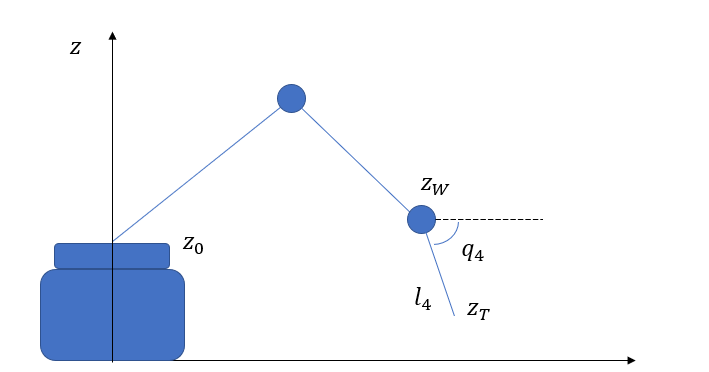

El objetivo, será conocer la posición de la muñeca, para lo que se comienza por conocer su altura.


$$z_W =z_T -l_4 \cdot \sin \;\left(q_4 \right)$$


zW = zT-l4*sind(q4)

$$zW = \mathrm{zT}+5$$

Desde la vista superior se tiene.

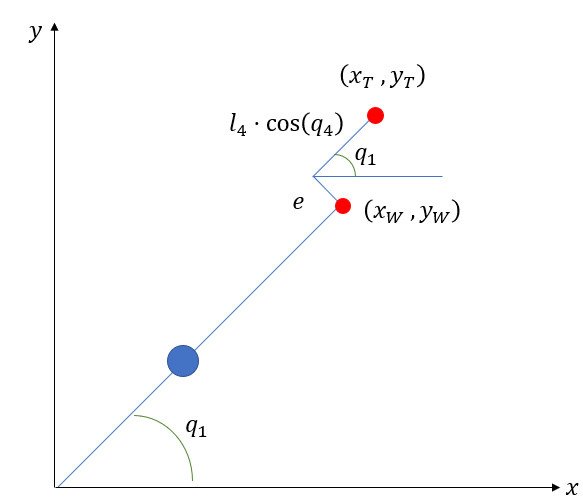

De donde, se encuentra la posición de la muñeca


$$x_W =x_T -l_4 \cdot \cos \left(q_4 \right)\cdot \cos \left(q_1 \right)+e\cdot \sin \left(q_1 \right)$$



$$y_W =y_T -l_4 \cdot \cos \left(q_4 \right)\cdot \sin \left(q_1 \right)-e\cdot \cos \left(q_1 \right)$$


xW = xT - l4*cosd(q4)*cos(q1) + e*sin(q1)

$$xW = \mathrm{xT}+5\,\sin\left(\text{atan2}\left(\mathrm{yT},\mathrm{xT}\right)-\text{atan2}\left(5,\sqrt{{\mathrm{xT}}^{2}+{\mathrm{yT}}^{2}}\right)\right)$$

yW = yT - l4*cosd(q4)*sin(q1) - e*cos(q1)

$$yW = \mathrm{yT}-5\,\cos\left(\text{atan2}\left(\mathrm{yT},\mathrm{xT}\right)-\text{atan2}\left(5,\sqrt{{\mathrm{xT}}^{2}+{\mathrm{yT}}^{2}}\right)\right)$$

De esta manera, los ángulos 2 y 3 pueden ser encontrados a través del teorema del coseno, para lo cual nos basamos en la figura

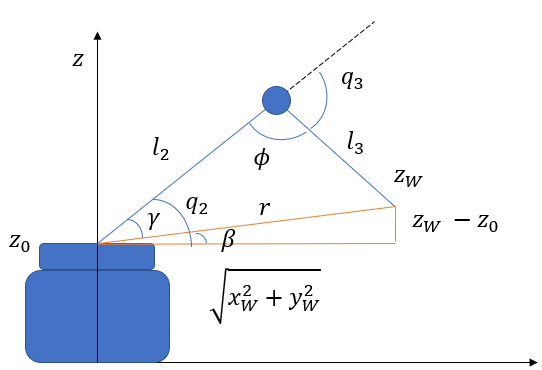

De esta manera, se encuentran los ángulos de interés a continuación.


$$\beta =\textrm{atan2}\;\left(z_W -z_0 \;,\sqrt{\;x_w^2 +y_w^2 }\right)$$



$$r^2 =x_W^2 +y_W^2 +{\left(z_W -z_0 \right)}^2$$



$$\gamma =\cos^{-1} \left(\frac{l_2^2 +r^2 -l_3^2 }{2\cdot r\cdot l_2 }\right)$$



$$\phi \;{=\;\cos }^{-1} \left(\frac{l_2^2 +l_3^2 -r^2 }{2\cdot l_2 \cdot l_3 }\right)$$



$$q_2 =\beta +\gamma$$



$$q_3 =\pi -\phi \;$$


beta = atan2(zW-z0, sqrt(xW^2+yW^2))

$$beta = \text{angle}\left(\mathrm{zT}\,\mathrm{i}+\sqrt{{\left(\mathrm{xT}+5\,\sin\left(\text{atan2}\left(\mathrm{yT},\mathrm{xT}\right)-\text{atan2}\left(5,\sqrt{{\mathrm{xT}}^{2}+{\mathrm{yT}}^{2}}\right)\right)\right)}^{2}+{\left(\mathrm{yT}-5\,\cos\left(\text{atan2}\left(\mathrm{yT},\mathrm{xT}\right)-\text{atan2}\left(5,\sqrt{{\mathrm{xT}}^{2}+{\mathrm{yT}}^{2}}\right)\right)\right)}^{2}}-5\,\mathrm{i}\right)$$

r = sqrt(xW^2 + yW^2 + (zW-z0)^2)

$$r = \sqrt{{\left(\mathrm{xT}+5\,\sin\left(\text{atan2}\left(\mathrm{yT},\mathrm{xT}\right)-\text{atan2}\left(5,\sqrt{{\mathrm{xT}}^{2}+{\mathrm{yT}}^{2}}\right)\right)\right)}^{2}+{\left(\mathrm{zT}-5\right)}^{2}+{\left(\mathrm{yT}-5\,\cos\left(\text{atan2}\left(\mathrm{yT},\mathrm{xT}\right)-\text{atan2}\left(5,\sqrt{{\mathrm{xT}}^{2}+{\mathrm{yT}}^{2}}\right)\right)\right)}^{2}}$$

gamma = acos((l2^2+r^2-l3^2)/2*r*l2)

$$gamma = \begin{array}{l} \mathrm{acos}\left(10\,\sqrt{\sigma_{1}+{\left(\mathrm{zT}-5\right)}^{2}+\sigma_{2}}\,\left(\frac{\sigma_{1}}{2}+\frac{{\left(\mathrm{zT}-5\right)}^{2}}{2}+\frac{\sigma_{2}}{2}+18\right)\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\mathrm{xT}+5\,\sin\left(\text{atan2}\left(\mathrm{yT},\mathrm{xT}\right)-\text{atan2}\left(5,\sqrt{{\mathrm{xT}}^{2}+{\mathrm{yT}}^{2}}\right)\right)\right)}^{2}\\ \sigma_{2}={\left(\mathrm{yT}-5\,\cos\left(\text{atan2}\left(\mathrm{yT},\mathrm{xT}\right)-\text{atan2}\left(5,\sqrt{{\mathrm{xT}}^{2}+{\mathrm{yT}}^{2}}\right)\right)\right)}^{2} \end{array}$$

phi = acos((l2^2+l3^2-r^2)/2*l2*l3)

$$phi = \mathrm{acos}\left(6560-40\,{\left(\mathrm{zT}-5\right)}^{2}-40\,{\left(\mathrm{yT}-5\,\cos\left(\text{atan2}\left(\mathrm{yT},\mathrm{xT}\right)-\text{atan2}\left(5,\sqrt{{\mathrm{xT}}^{2}+{\mathrm{yT}}^{2}}\right)\right)\right)}^{2}-40\,{\left(\mathrm{xT}+5\,\sin\left(\text{atan2}\left(\mathrm{yT},\mathrm{xT}\right)-\text{atan2}\left(5,\sqrt{{\mathrm{xT}}^{2}+{\mathrm{yT}}^{2}}\right)\right)\right)}^{2}\right)$$

q2 = beta + gamma

$$q2 = \begin{array}{l} \text{angle}\left(\mathrm{zT}\,\mathrm{i}+\sqrt{\sigma_{1}+\sigma_{2}}-5\,\mathrm{i}\right)+\mathrm{acos}\left(10\,\sqrt{\sigma_{1}+{\left(\mathrm{zT}-5\right)}^{2}+\sigma_{2}}\,\left(\frac{\sigma_{1}}{2}+\frac{{\left(\mathrm{zT}-5\right)}^{2}}{2}+\frac{\sigma_{2}}{2}+18\right)\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\mathrm{xT}+5\,\sin\left(\text{atan2}\left(\mathrm{yT},\mathrm{xT}\right)-\text{atan2}\left(5,\sqrt{{\mathrm{xT}}^{2}+{\mathrm{yT}}^{2}}\right)\right)\right)}^{2}\\ \sigma_{2}={\left(\mathrm{yT}-5\,\cos\left(\text{atan2}\left(\mathrm{yT},\mathrm{xT}\right)-\text{atan2}\left(5,\sqrt{{\mathrm{xT}}^{2}+{\mathrm{yT}}^{2}}\right)\right)\right)}^{2} \end{array}$$

q3 = pi - phi

$$q3 = \pi -\mathrm{acos}\left(6560-40\,{\left(\mathrm{zT}-5\right)}^{2}-40\,{\left(\mathrm{yT}-5\,\cos\left(\text{atan2}\left(\mathrm{yT},\mathrm{xT}\right)-\text{atan2}\left(5,\sqrt{{\mathrm{xT}}^{2}+{\mathrm{yT}}^{2}}\right)\right)\right)}^{2}-40\,{\left(\mathrm{xT}+5\,\sin\left(\text{atan2}\left(\mathrm{yT},\mathrm{xT}\right)-\text{atan2}\left(5,\sqrt{{\mathrm{xT}}^{2}+{\mathrm{yT}}^{2}}\right)\right)\right)}^{2}\right)$$